# Relazione di Controllo dei Sistemi Incerti:

# “Robust Control of Self-Balacing Two Wheeled Robot”

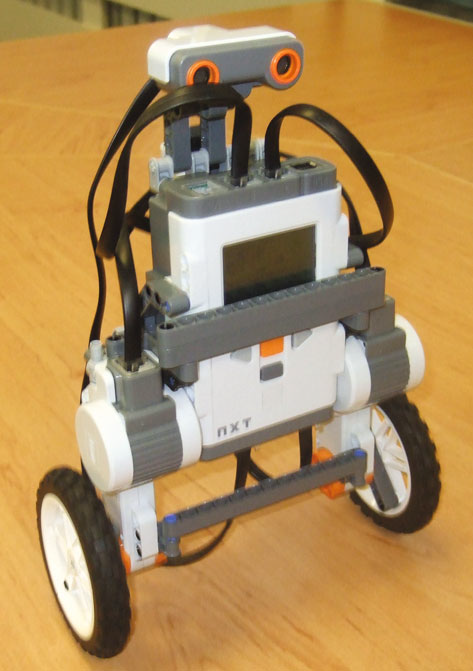

## Introduzione:

L’obiettivo del progetto è progettare un controllore robusto per un “Self-Balacing Two Wheeled Robot”. Il robot è costruito usando il kit LEGO Minstorms NXT, insieme ad un microcontrollore ATMEL su cui è implementato l’algoritmo di controllo.

Il sistema possiede inoltre dei sensori quali un giroscopio per misurare l’angolo di Tilt e degli encoder su entrambe le ruote, per misurare la rotazione imposta dai motori. 

Il controllo dei motori DC viene fatto con il PWM.

Il sensore ad ultrasuoni è messo per un’eventuale applicazione di Obstacle Avoidance.

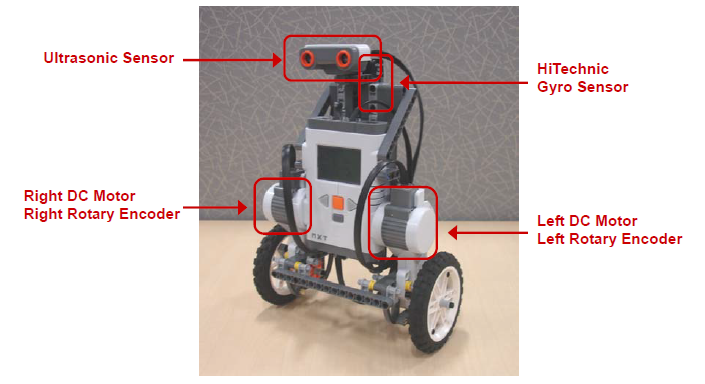

## Modello Incerto:

Il robot può essere facilmente modellabile come un pendolo inverso, dove la forza f è risultante dalla rotazione delle due ruote alla base. 

Il modello non lineare è ricavabile dalle eq. Di Lagrange e poi successivamente linearizzate intorno ad un punto di equilibrio. Il modello linearizzato ha dunque la forma:

 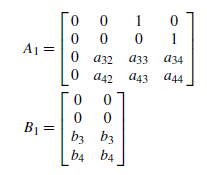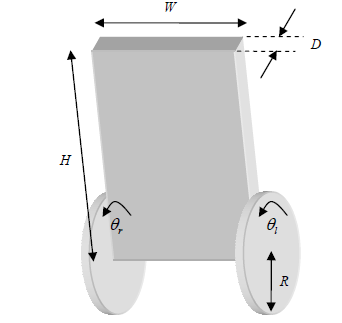

Dove il vettore di stato è:

 

- L’angolo θ risulta la media tra gli angoli di rotazione delle ruote.

- L’angolo ψ risulta l’angolo di tilt rispetto alla verticale del robot, indispensabile per l’equilibrio.

- L’angolo Ф risulta l’angolo di imbardata. 

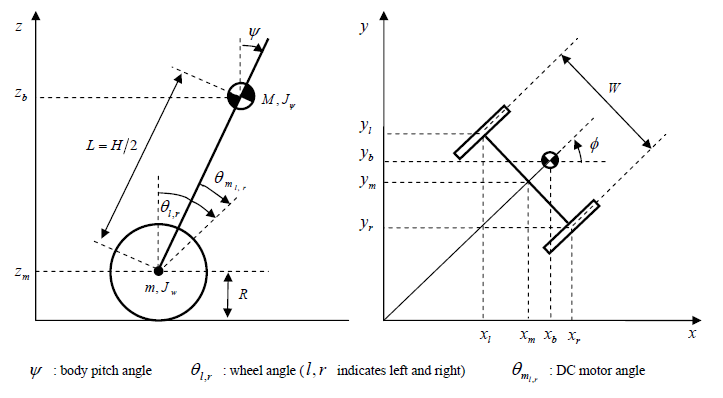

 I singoli elementi delle matrici A e B sono dati dai parametri fisici del sistema e dei loro valori nominali.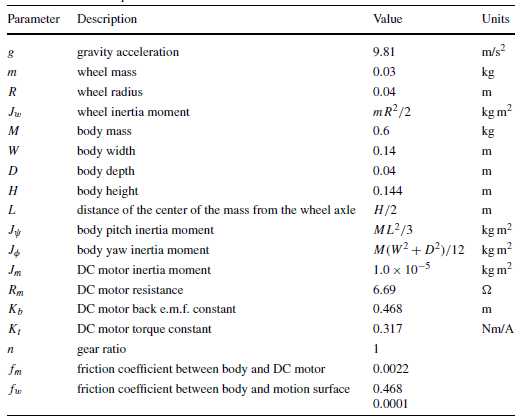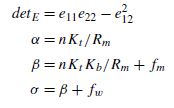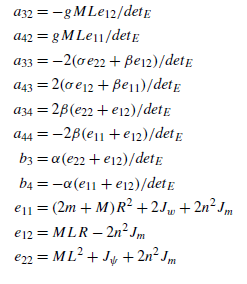

Il parametro che interviene in tutti i coefficienti del sistema è sicuramente la massa M. Tuttavia, considerare la massa come parametro incerto, equivarrebbe ad avere un blocco M-Δ con il blocco delle incertezze 52x52. Il progetto del controllore quindi risulta essere molto complesso o addirittura impossibile. 

Dunque si considerano incerti i parametri soltanto i due coeff. di attrito fm e fw. Il primo rappresenta l’attrito tra il robot e il motore DC, mentre il secondo tra il robot e il terreno. 

- **f****m****: **Attrito tra il robot e il motore DC; incertezza del 20% del valore nominale.

- **f****w****: **Attrito tra il robot e il terreno; incertezza del 100% del valore nominale.

Per l'implementazione dei due parametri incerti in Matlab:

Il modello è poi costruito grazie allo script mod_robot.m, che eseguito da luogo al sistema incerto:

mod_robot
G_unc

G_unc =

  Uncertain continuous-time state-space model with 4 outputs, 2 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.00176,0.00264], 1 occurrences
    fw: Uncertain real, nominal = 0.0001, range = [1.36e-20,0.0002], 1 occurrences

Type "G_unc.NominalValue" to see the nominal value, "get(G_unc)" to see all properties, and "G_unc.Uncertainty" to interact with the uncertain elements.



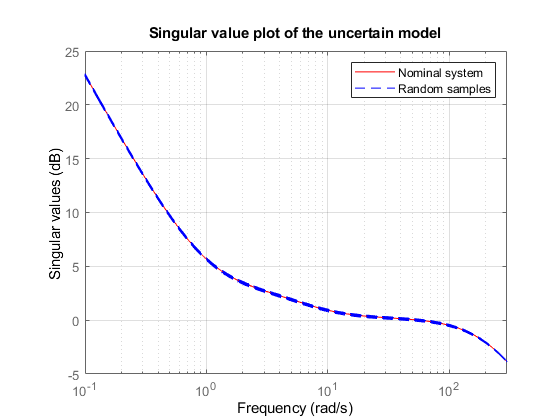

sigma(G_unc.Nominal,'r-',G_unc,'b--'), grid
axis([10^(-1) 3*10^2 -5 25])
xlabel('Frequency')
ylabel('Singular values')
title('Singular value plot of the uncertain model')
legend('Nominal system','Random samples')

Notiamo che la variazione della risposta in frequenza, rispetto a variazioni randomiche delle incertezze, risultano piccole. Ci aspettiamo dunque che le incertezze siano piccole in modulo. Il modello del robot è schematizzato come segue.

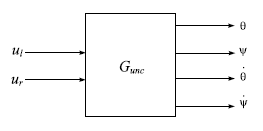

## Progetto del Controllore $\mu$:

Per la progettazione del controllo robusto attraverso la $\mu 
$-synthesis, occorre costruire un sistema interconnettendo il sistema con le relative funzioni di peso. 

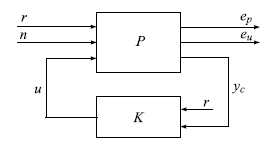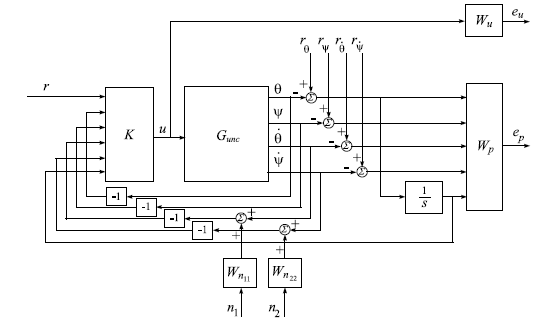

Dall'esperienza, si è visto che è difficile l'angolo $\theta$ vada a riferimento. Per questo si aggiunge un vincolo sull'integrale dell'angolo, per migliorarne l'andamento a regime. 

L'interconnessione è implementata dallo script:

olp_robot_2dof

Le matrici di peso sono:

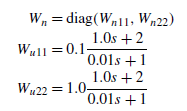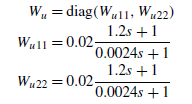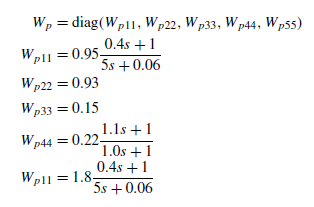

Il comando usato per l'interconnessione è:

## Sintesi $\mu$:

La sintesi del controllore è implementata dalla funzione dksyn, restituendo un controllore del 12° ordine. Lo script che lo implementa è: dms_robot_2dof.m.

Il risultato delle iterazioni D-K sono riassunte nella tabella:

Si vede dunque che alla terza iterazione, il controllore ottiene un picco del valore singolare strutturato di 0.930. Di conseguenza, il controllore rispetta la robusta prestazione per variazioni di entrambi i parametri incerti.

## Proprietà del sistema a Ciclo Chiuso:

#### Risposta in frequenza:

La risposta in frequenza del sistema in anello chiuso è mostrata dallo script:

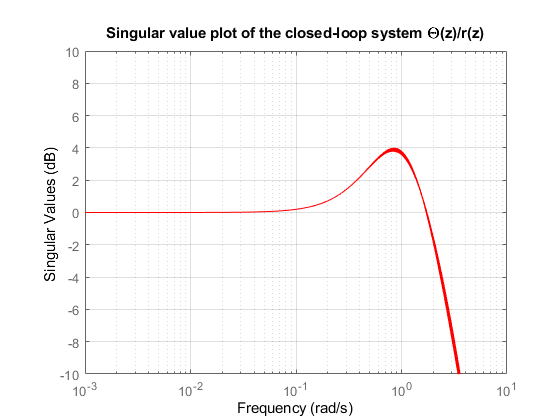

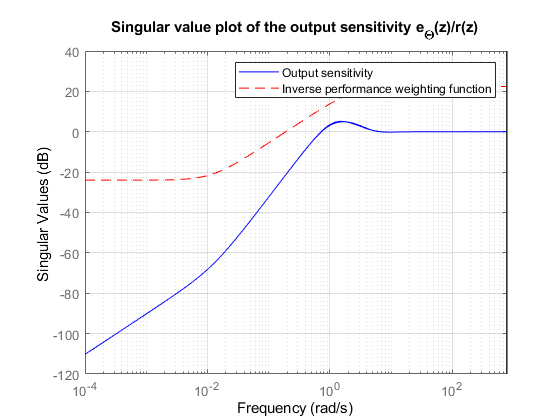

dfrs_robot_2dof

Il primo grafico mostra come la risposta in frequenza a ciclo chiuso sia accettabile e con una pulsazione di taglio di 2.13 rad/s. Il secondo, mostra come la f. di sensitività rispetti il vincolo dato dalle funzioni di peso.

#### Analisi $\mu$ per la Robusta Stabilità e Prestazione:

L'analisi di robustezza è implementata dallo script dmu_robot_2dof.m e in particolare dai comandi:

Da cui:

Points completed: 200/200
ROBUSTSTAB Sensitivity calculations are beginning.
      Uncertain element fm...
      Uncertain element fw...


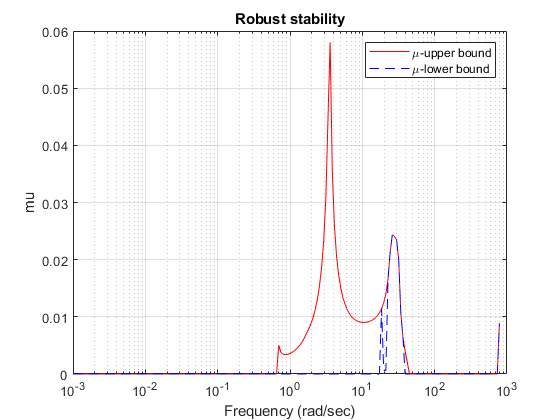

Points completed: 200/200
ROBUSTSTAB Sensitivity calculations are beginning.
      Uncertain element fm...
      Uncertain element fw...


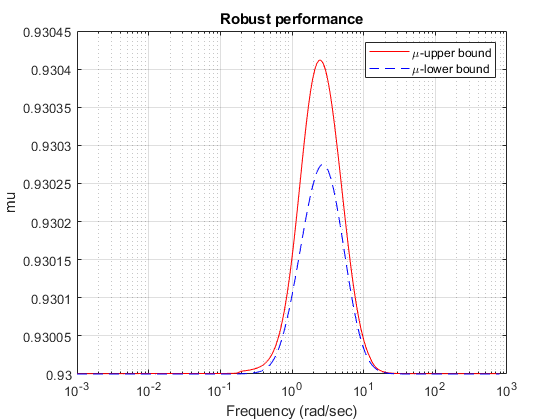

dmu_robot_2dof

Notiamo che la robusta stabilità è rispettata e il valore singolare strutturato non supera il valore di 0.063. Anche la robusta prestazione è rispettata, ma al contrario della r.s., il valore massimo del valore singolare strutturato è di 0.9304. Dunque un'incertezza grande 1.075 volte quella già esistente fa perdere la robusta prestazione al sistema in catena chiusa.

Il worst case è mostrato dallo script:

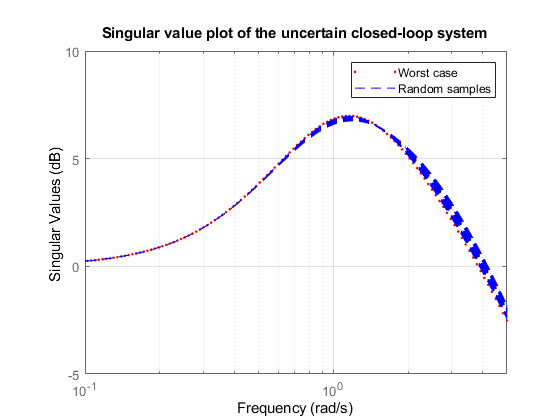

wcp_robot_2dof

#### Risposta nel dominio del tempo:

La risposta al transitorio è implementata dallo script.

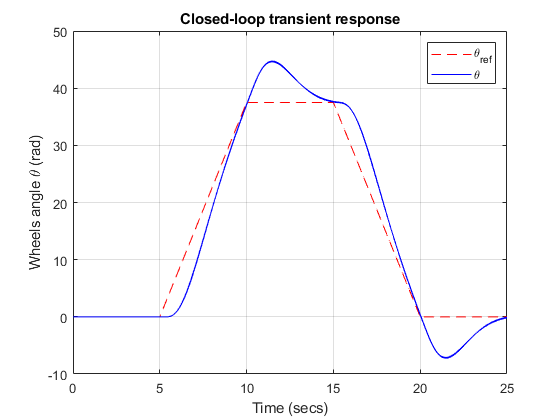

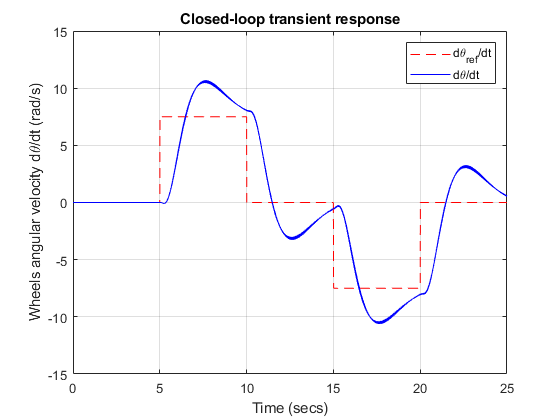

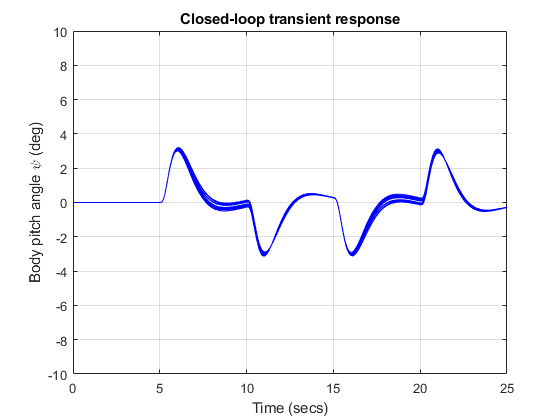

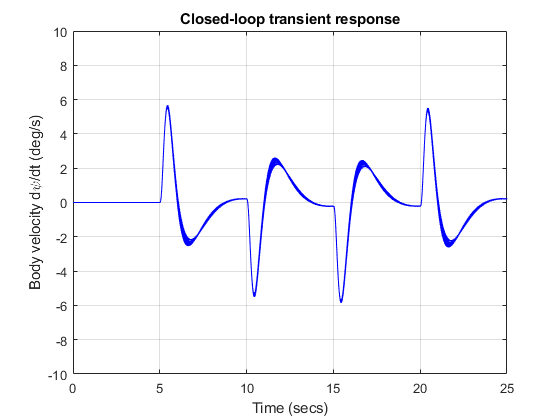

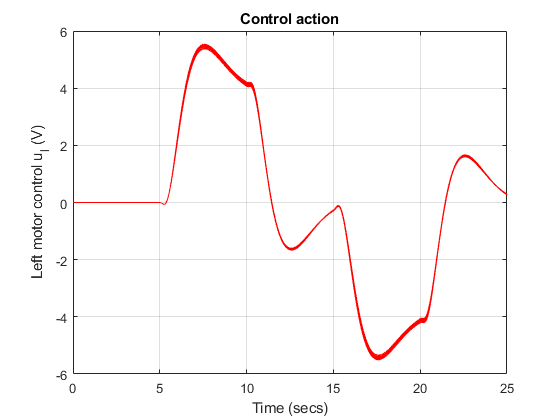

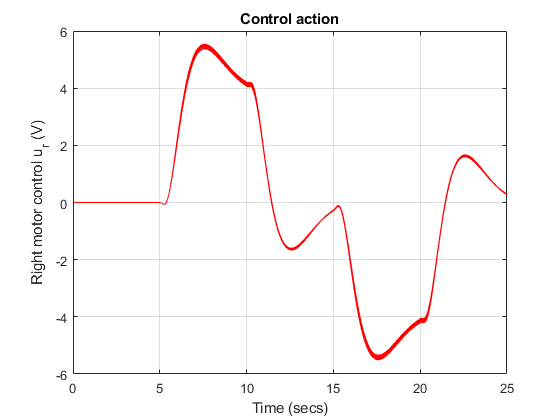

mcs_robot_2dof

## Progetto del controllore LQG/LTR:

Per il progetto del controllore LQG con recupero LTR, bisogna seguire dei passi per riadattare le specifiche tipiche del controllore $\mu$, in specifiche sui valori singolari. Dato che le incertezze sono negli attuatori, è opportuno eseguire l'apertura di anello in ingresso. 

Gli step per la sintesi del controllore sono diversi, di seguito elencati.

- Prerequisiti: Sistema a fase non minima e quadrato. 

- Aggiungere un banco di integratori, a seconda del tipo di riferimento da inseguire.

- Convertire il set di incertezze parametriche in incertezze non strutturate di tipo moltiplicativo.

- Tuning di $H$ e $\rho$.

- Verifica dei vincoli in bassa freq: $\frac{1}{\sqrt{\rho}}\underline{\sigma}(H\Phi B) > \frac{p(\omega)}{1-l_m(\omega)}$

- Verifica dei vincoli in alta freq: $\overline{\sigma} \left(\frac{HB}{\sqrt\rho} \right) = \omega_{cmax} \le \omega_c \qquad dove \quad l_m(\omega_c) = 0dB$

- Sintesi LQR con le matrici di peso $Q= H^{T}H \quad R=\rho I$

- Verifico che in bassa freq. vale: $\sigma_i(K_c\Phi B) \approx\frac{1}{\sqrt{\rho}} \sigma_i(H\Phi B)$

- Sia $T_{LQ}=K_c\Phi B$, verifico:

- 
$$\sigma_i(I + T_{LQ}^{-1}) \ge -6 dB$$


- 
$$\overline{\sigma}(T_{LQ}(I + T_{LQ})^{-1}) < \frac{1}{l_m(\omega)}$$


- Usando il comando ltrsyn, eseguiamo il recupero attraverso il filtro di Kalman, con $\Gamma \quad \mu$ parametri che compongono le matrici di covarianza del disturbo di processo e rumore di misura. In particolare: $Q_0=\Gamma\Gamma^{T} \quad R_0=\mu I$

- Sia $T_{INP}(s)=K_{LQG}(s)G(s)$, verifico che $\sigma_i(T_{INP}) \approx \sigma_i(T_{LQ})$

- Verifica finale di robustezza: $\underline{\sigma}(I+ T_{INP}^{-1}) \ge -6dB$

Di seguito quindi, vedremo come sono stati implementati i passaggi nello specifico sistema.

#### Considerazioni preliminari sul sistema:

Come abbiamo visto in precedenza, il sistema incerto G(s) è di dimensioni 4x2, con 4 uscite e 2 ingressi. Dato che la B risulta non a rango massimo (una colonna è lin. dipendente alla prima), il secondo ingresso risulta totalmente ridondante. Ciò ha un riscontro fisico, in quanto i due ingressi rappresentano il comando dato ai motori della ruota sx e dx. La G(s) sarà dunque sempre di rango unitario. Ciò è evidente anche quando si plottano i valori singolari in bode. 

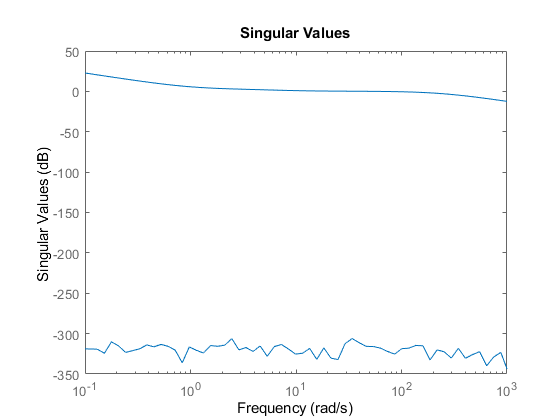

sigma(G_unc.NominalValue)

Notiamo infatti che il secondo valore singolare ha un'ampiezza molto bassa (intorno ai -300dB). Le sue oscillazioni sono dovute ai rumori numerici per il calcolo della risposta in frequenza. Per evitare che questo crei problemi nella sintesi, faremo alcune considerazioni per eliminare un ingresso e ricondurci ad un sistema SIMO. Infatti:


$$Y(s)= [ g_1(s) \quad g_1(s)]\  [U_1 \quad U_2(s)]^T \\
Y(s)=g_1(s)(U_1(s) + U_2(s))
$$


Dunque se $U(s)= U_1 + U_2, \quad allora \quad Y(s)=g_1(s)U(s)$.

Il sistema finale è dunque:


$$g_1(s) = \pmatrix{\frac{157.58(s-8.493)(s+8.493)}{s(s+241.6)(s-7.431)(s+6.539)} \cr \frac{-75.958(s+0.07062)}{(s+241.6)(s-7.431)(s+6.539)} \cr \frac{157.58(s-8.493)(s+8.493)}{(s+241.6)(s-74.31)(s+6.539)} \cr \frac{-75.958s(s+0.07062)}{(s+241.6)(s-7.431)(s+6.539)} }$$


Notiamo subito che il sistema risulta a fase non minima. La sintesi dell'LTR ci aspettiamo non sia performante e che potrebbe divergere, vista l'ipotesi della fase minima volata.

Notiamo poi che il sistema è di tipo 1, quindi non occorre un banco di integratori per l'inseguimento di un riferimento a gradino.

#### Da incertezze strutturate a Incertezze non strutturate:

Per il recupero dei margini, occorre che le incertezze siano di tipo non strutturato e moltiplicativo. 

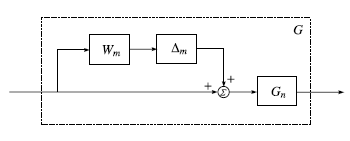

Possiamo dunque considerare:


$$W_m(s)= \pmatrix{ w_1(s) & 0 & 0 & 0 \cr 0 & w_2(s) & 0 & 0 \cr 0 & 0 & w_3(s) & 0 \cr  0 & 0 & 0 & w_4(s)} \qquad \tilde{G}= (I+W_m \Delta)G(s) = \pmatrix{ (1+w_1 \Delta_1)g_1(s) \cr (1+w_2 \Delta_2)g_2(s) \cr (1+w_3 \Delta_3)g_3(s) \cr (1+w_4 \Delta_4)g_4(s)}$$


Dunque per ricavare l'incertezza strutturata, possiamo applicare la formula:


$$\frac{|\tilde{g}_i - g_i|}{|g_i|} < |w_i|$$


Facendo variare i parametri incerti all'interno del range noto e ricavare un set di incertezze. Con lo script wfit.m, possiamo fittare la risposta in frequenza, ricavando una funzione di peso w(s) che limita superiormente la famiglia di risposte in frequenze.

Per facilitare la conversione, abbiamo considerato incerto soltanto l'incertezza su fm, più influente dell'incertezza fw.

unstr_unc

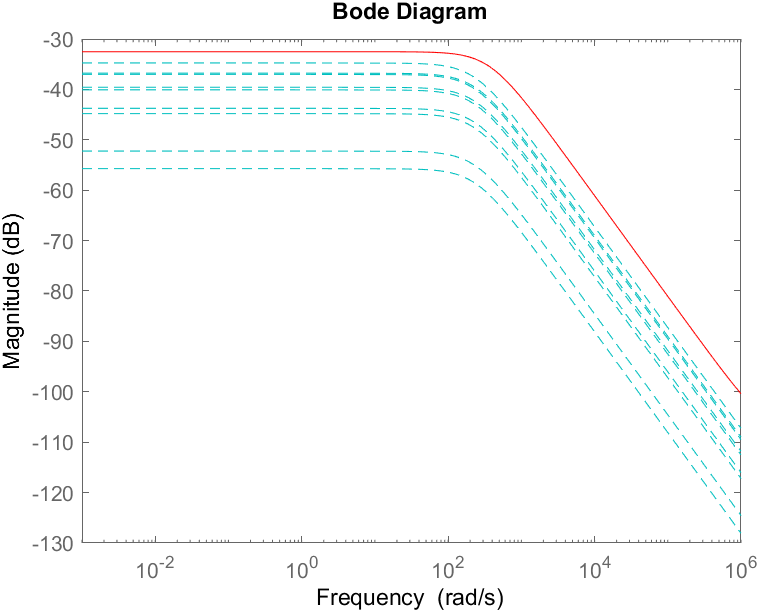

Analogamente, per la funzione di peso p(w), è possibile ricavarla come upper bound dei valori singolari della matrice di peso delle prestazioni.

### Sintesi LQG/LTR

Per la sintesi dell'LQG e del recupero attraverso l'iterazione su q, usiamo lo script ltr.m. 

Otteniamo quindi i vari step, con i relativi grafici:

#### Tuning H e $\rho$:

Bassa frequenza: $\frac{1}{\sqrt{\rho}}\underline{\sigma}(H\Phi B) > \frac{p(\omega)}{1-l_m(\omega)}$

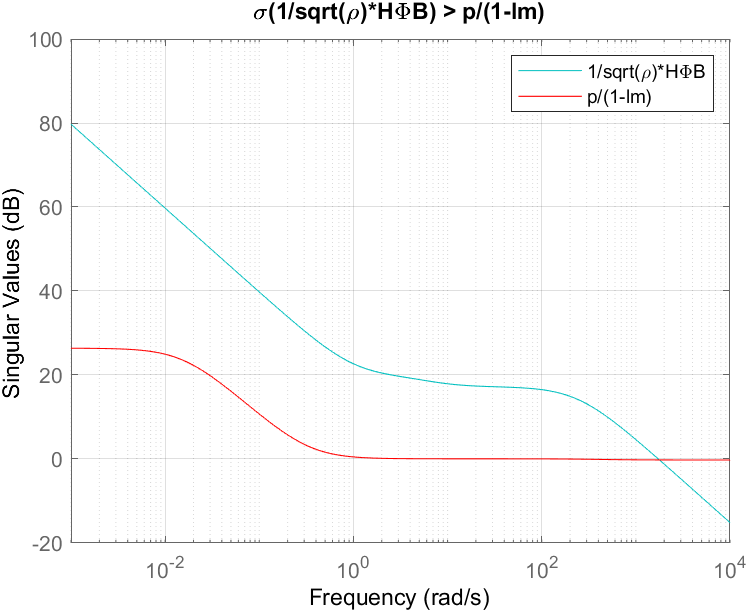

Dato che l'incertezza non ha un attraversamento allo 0, in quanto è sempre al di sotto dell'asse 0dB. Non abbiamo dunque un vincolo sulle alte frequenze.

#### Sintesi LQR:

Trovati i due parametri, è possibile dunque effettuare l'LQR attraverso il comando, ricavando il guadagno Kc.

Verifico che:


$$\sigma_i(K_c\Phi B) \approx\frac{1}{\sqrt{\rho}} \sigma_i(H\Phi B)$$


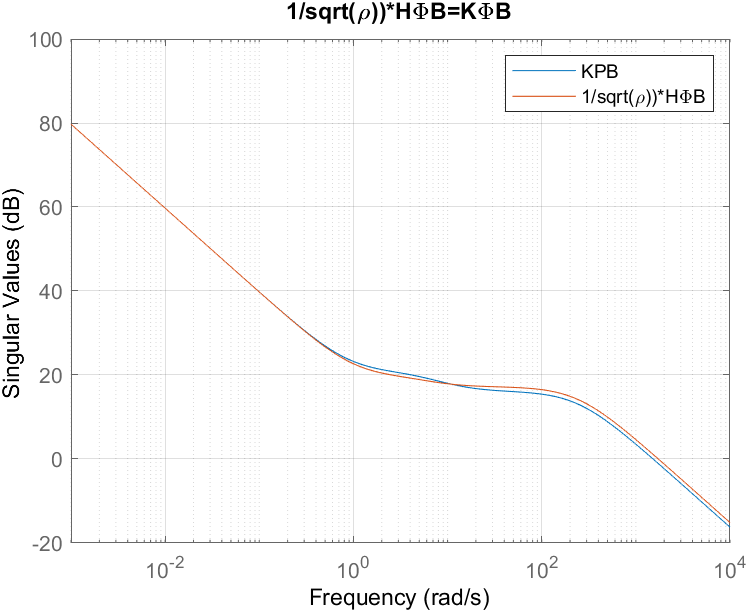


$$\sigma_i(I + T_{LQ}^{-1}) \ge -6 dB$$


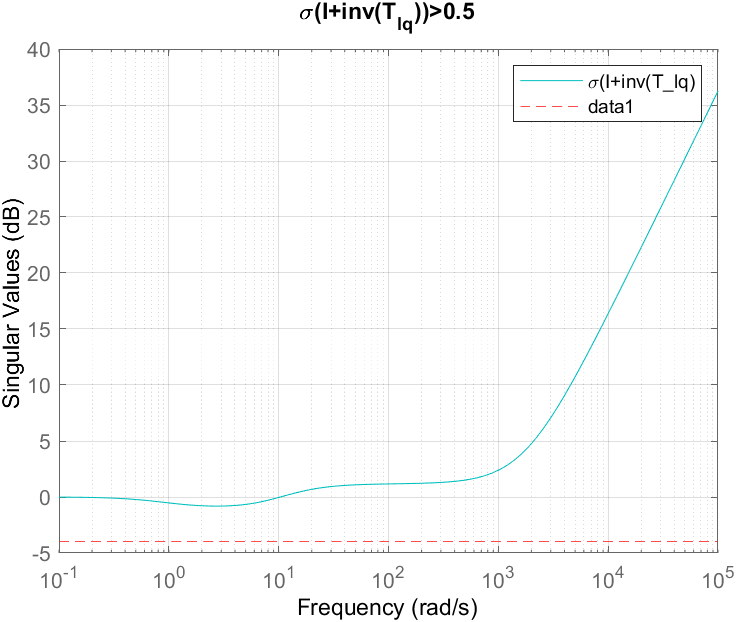


$$\overline{\sigma}(T_{LQ}(I + T_{LQ})^{-1}) < \frac{1}{l_m(\omega)}$$


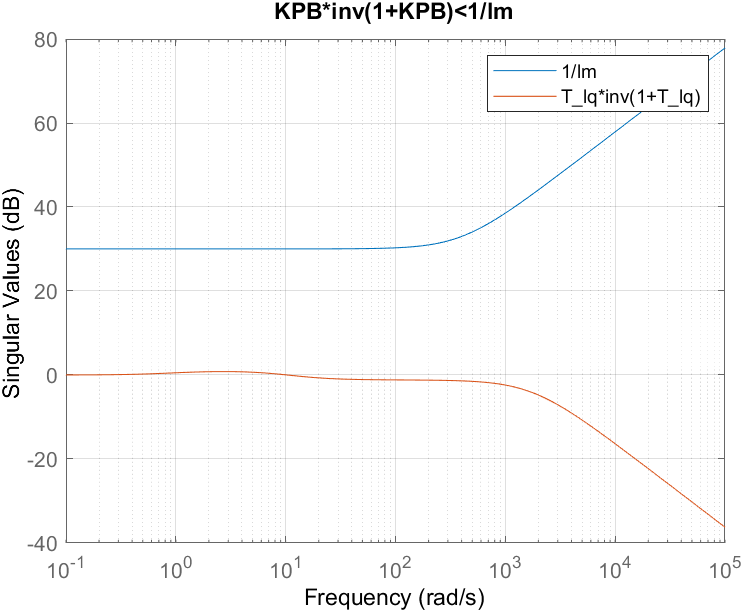

#### Recupero con il KBF:

Il recupero viene implementato dal comando: 

E' possibile vedere gli effetti delle iterazioni di q:

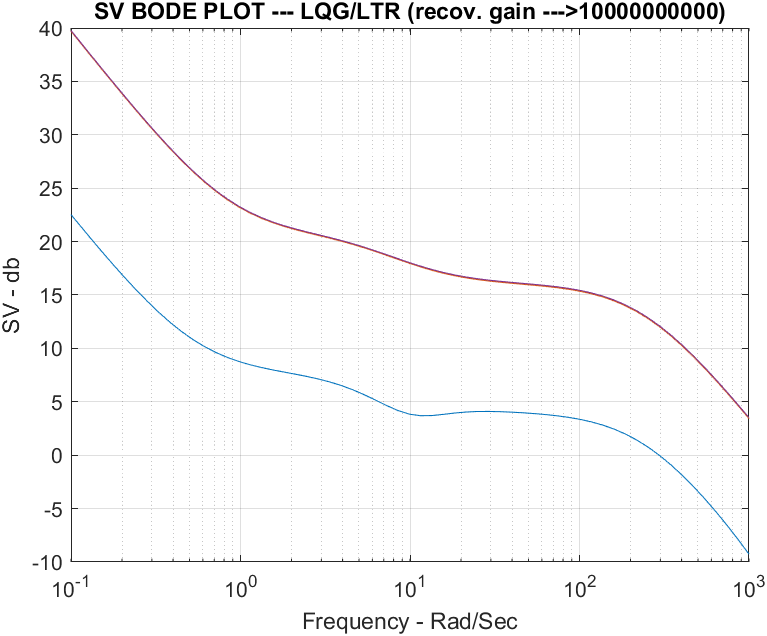

Verifiche finali:


$$\sigma_i(T_{INP}) \approx \sigma_i(T_{LQ})$$
 

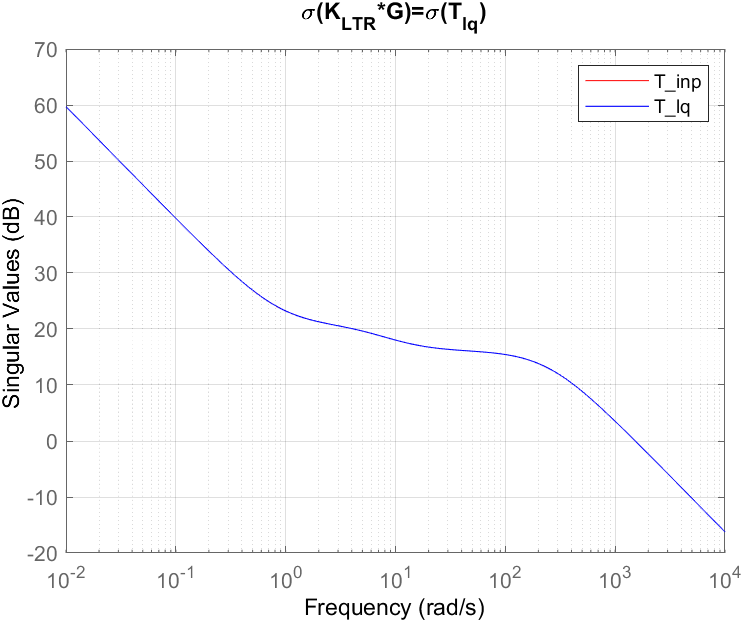


$$\underline{\sigma}(I+ T_{INP}^{-1}) \ge -6dB$$


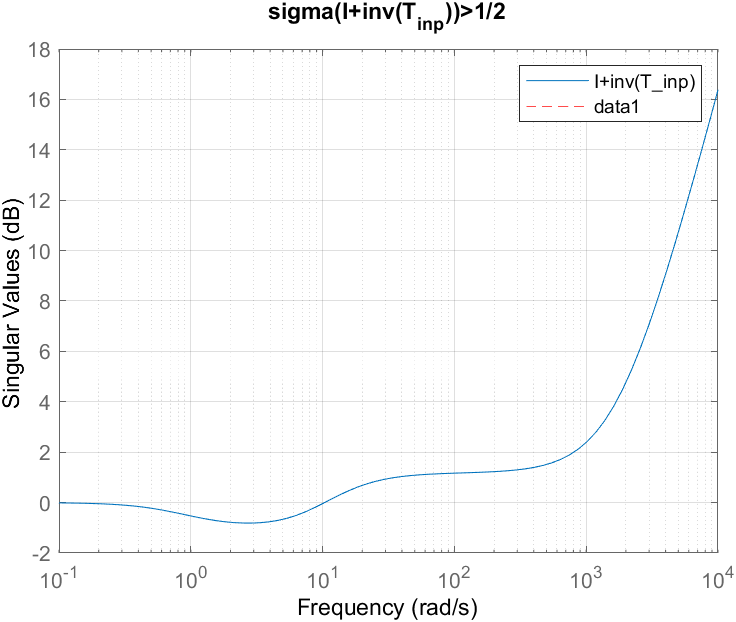

## Robusta Stabilità e Robusta Prestazione:

Attraverso lo script:

Points completed: 200/200
ROBUSTSTAB Sensitivity calculations are beginning.
      Uncertain element fm...
      Uncertain element fw...


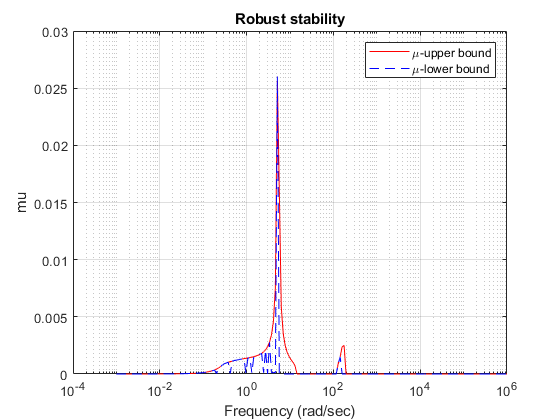

Points completed: 200/200
ROBUSTSTAB Sensitivity calculations are beginning.
      Uncertain element fm...
      Uncertain element fw...


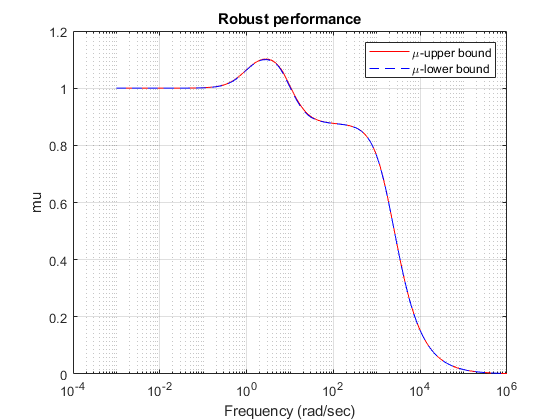

mu_ltr

Mentre la robusta stabilità è ampiamente rispettata, la robusta prestazione invece non è garantita. Infatti in bassa frequenza abbiamo un picco in 1.01. Ciò è dovuto alla fase non minima del sistema e alla non quadratura dello stesso, violando alcune ipotesi di fondo dell'LTR. 

### Risposta al gradino:

Notiamo che il sistema insegue correttamente il riferimento, con un tempo di assestamento di circa 4 secondi. Vediamo che la famiglia di incertezze non si discosta troppo dal caso nominale. 

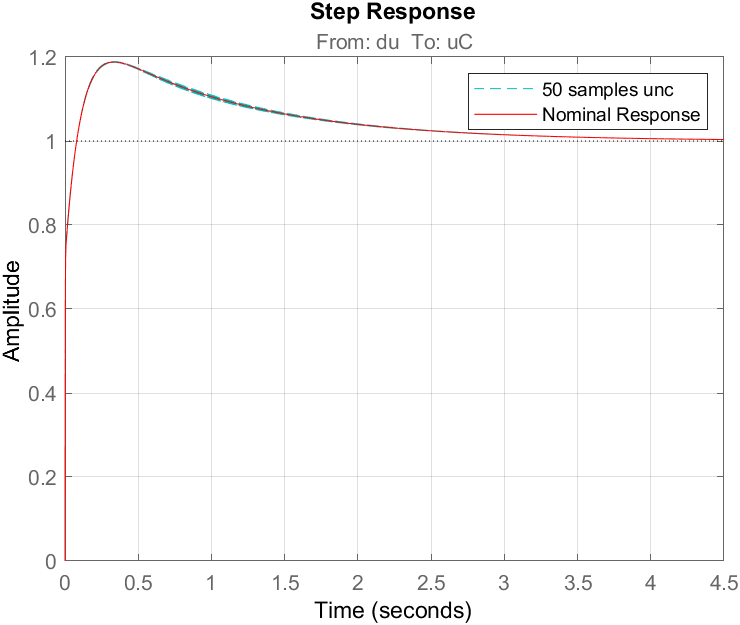

## Conclusioni:

•Il controllore LQG/LTR risulta meno performante rispetto al caso µ. Questo è dovuto sia alla presenza di incertezze strutturate che al fatto che il sistema sia a fase non minima.

•E’ possibile diminuire il picco dell’SSV nella RP, nel caso LQG/LTR, diminuendo ρ. Tuttavia questo comporta un aumento del guadagno che può non riscontrare senso fisico negli attuatori. 

•Non è stato necessario aggiungere un’azione integrale al sistema, per il riferimento a gradino, in quanto il sistema stesso era di tipo 1.